Compute qqplot for BCHF

have 6 cases to deal with, go through sequentially

case 1 ExactlyOneATwoAllele High Frequency -- must be only het diploytpes

%% ExactTwoLFCase

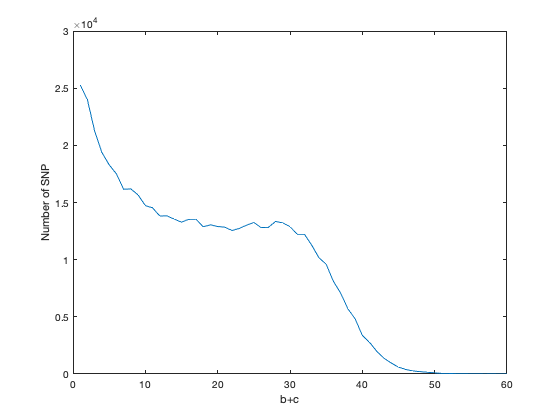

NumInformativePairs  = max(McNemarsResult.("ExactTwoLF_b+c"));

for n = 1:NumInformativePairs
    % for n = 1:5
    for i=0:1:n
        b = i;
        c = n - i;
        Theoretical_Mid_p_Distro(n,i+1) = mid_p_value(b,c,0.5); 
        Theoretical_Exact_p_Distro(n,i+1) = exact_p_value(b,c,0.5); 
    end
end

% mid-p values for a given n (b+c) usually sum to greater than one, need to
% normalize for qqplot and othe statistics

for n = 1:NumInformativePairs % have to do this is separate step because total array size includes trailing zeros
    Normalized_Theoretical_Mid_p_Distro(n,:) = ...
        Theoretical_Mid_p_Distro(n,:)/sum(Theoretical_Mid_p_Distro(n,:));
    Normalized_Theoretical_Exact_p_Distro(n,:) = ...
        Theoretical_Exact_p_Distro(n,:)/sum(Theoretical_Exact_p_Distro(n,:));
    
end

%  ObserveredInformativePairClass = a given b+c 
%  ObserveredInformativePairMembers = number of times a given b+c is observed

% calculate statistics based on SNP vs b+c, calculate expected vs observed
%
% loop over each SNP in McNemarsReults, a MatLab table


for i = 1:NumInformativePairs
    ObserveredInformativePairClass(i) = i;
    
    %rows_with_b_plus_c = rows
    
    % find members of class
    
    NumberSNP_b_plus_c(i) = nnz((McNemarsResult.("ExactTwoLF_b+c") == i));   
end

plot(NumberSNP_b_plus_c)
xlabel("b+c")
ylabel("Number of SNP")
hold off


Theoretical_Mid_p_values_array_for_all_SNP = [];
Theoretical_Mid_p_values_array_for_SNP_temp = 0;
Num_SNP_per_mid_p_value = [];

for i = 1:height(Normalized_Theoretical_Mid_p_Distro)

    Number_Mid_p_values = nnz(Normalized_Theoretical_Mid_p_Distro(i,:));

    for k = 1:Number_Mid_p_values
        

        Num_SNP_per_mid_p_value(k) = round(NumberSNP_b_plus_c(i) * ...
            Normalized_Theoretical_Mid_p_Distro(i,k));
        
         % create array holding mid-p-values corresponding to number of SNP with
          % with b+c = i

        Theoretical_Mid_p_values_array_for_SNP_temp = ones(1,Num_SNP_per_mid_p_value(k)) * ...
            Theoretical_Mid_p_Distro(i,k);

        Theoretical_Mid_p_values_array_for_all_SNP = horzcat(Theoretical_Mid_p_values_array_for_all_SNP, ...
            Theoretical_Mid_p_values_array_for_SNP_temp);
        
    end

end

filtered_Theoretical_Mid_p_values_array_for_all_SNP = round(Theoretical_Mid_p_values_array_for_all_SNP,6);

filler = [0.5,0.5];

filtered_Theoretical_Mid_p_values_array_for_all_SNP = horzcat(filler,filtered_Theoretical_Mid_p_values_array_for_all_SNP);


% Compute predicted mid-p-vals_array_for_all_SNP = horue distribution for each b+c combinataion on

McNemarsResult_Row_First_Filter = McNemarsResult.("ExactTwoLF_b+c") > 0. ;

% McNemarsResult_Row_Filter = McNemarsResult.("ExactTwoLF_p_mid") < 0.9;

McNemarsResult_b_plus_c = McNemarsResult(McNemarsResult_Row_First_Filter,:);


filtered_McNemarsResult_b_plus_c_Mid_p= round(McNemarsResult_Filtered_b_plus_c.("ExactTwoLF_p_mid"),6);


% Sort arrays for plink like qqplot 
sorted_filtered_Mid_p_values_array_for_all_SNP = sort(filtered_Theoretical_Mid_p_values_array_for_all_SNP');
sorted_McNemarsResult_Filtered_b_plus_c_Mid_p = sort(filtered_McNemarsResult_b_plus_c_Mid_p);

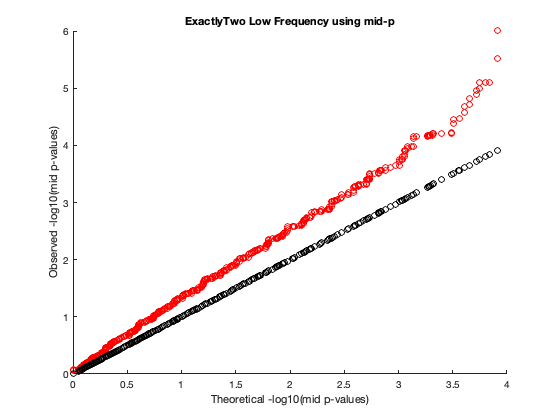

figure;
hold on

scatter(-log10(sorted_filtered_Mid_p_values_array_for_all_SNP),-log10(sorted_McNemarsResult_Filtered_b_plus_c_Mid_p),'red')
scatter(-log10(sorted_filtered_Mid_p_values_array_for_all_SNP),-log10(sorted_filtered_Mid_p_values_array_for_all_SNP),'black')
xlabel("Theoretical -log10(mid p-values)")
ylabel("Observed -log10(mid p-values)")
title("ExactlyTwo Low Frequency using mid-p")

hold off

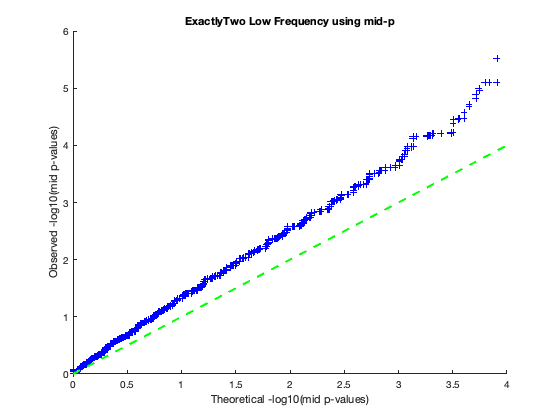


figure
hold on
qqplot(-log10(filtered_Theoretical_Mid_p_values_array_for_all_SNP),-1*log10(sorted_McNemarsResult_Filtered_b_plus_c_Mid_p))
xlabel("Theoretical -log10(mid p-values)")
ylabel("Observed -log10(mid p-values)")
title("ExactlyTwo Low Frequency using mid-p")
BaseLineX = [0,4];
BaseLineY = [0,4];
plot(BaseLineX,BaseLineY,'--','Color','g','LineWidth', 2)
hold off

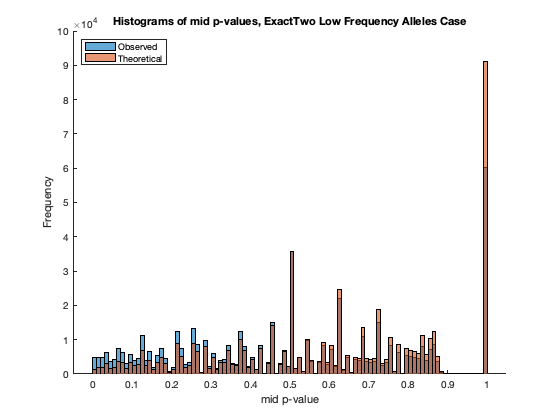

figure
hold on

histogram(sorted_McNemarsResult_Filtered_b_plus_c_Mid_p)
histogram(filtered_Theoretical_Mid_p_values_array_for_all_SNP)
legend('Observed','Theoretical', 'Location','northwest')
title('Histograms of mid p-values, ExactTwo Low Frequency Alleles Case')
xlabel('mid p-value')
ylabel('Frequency')

hold off

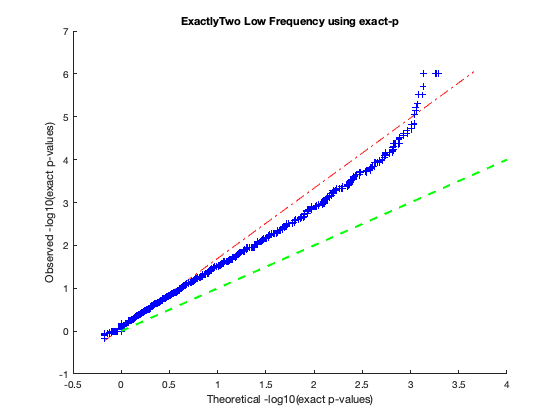

Exact_p_values_array_for_all_SNP = [];
Exact_p_values_array_for_SNP_temp = 0;

for i = 1:height(Normalized_Theoretical_Exact_p_Distro)

    number_exact_p_values = nnz(Normalized_Theoretical_Exact_p_Distro(i,:));

    for k = 1:number_exact_p_values

        Num_SNP_per_exact_p_value(k) = round(NumberSNP_b_plus_c(i) * ...
            Normalized_Theoretical_Exact_p_Distro(i,k));
        
         % create array holding mid-p-values corresponding to number of SNP with
          % with b+c = i

        Exact_p_values_array_for_SNP_temp = ones(1,Num_SNP_per_exact_p_value(k)) * ...
            Theoretical_Exact_p_Distro(i,k);

        Exact_p_values_array_for_all_SNP = horzcat(Exact_p_values_array_for_all_SNP, ...
            Exact_p_values_array_for_SNP_temp);
    end

end

%Exact_p_values_array_for_all_SNP_filter = Exact_p_values_array_for_all_SNP;
% filtered_Exact_p_values_array_for_all_SNP = Exact_p_values_array_for_all_SNP(Exact_p_values_array_for_all_SNP_filter);

filtered_Exact_p_values_array_for_all_SNP = round(Exact_p_values_array_for_all_SNP,6);

McNemarsResult_Row_First_Filter = McNemarsResult.("ExactTwoLF_b+c") > 0. ;
McNemarsResult_Filtered_b_plus_c = McNemarsResult(McNemarsResult_Row_First_Filter,:);

%McNemarsResult_Row_Second_Filter= round(McNemarsResult_Filtered_b_plus_c.("ExactTwoLF_p_exact"),6);
%McNemarsResult_Filtered = McNemarsResult_Filtered_b_plus_c(McNemarsResult_Row_Second_Filter,:);

figure
hold on
qqplot(-log10(filtered_Exact_p_values_array_for_all_SNP),-log10(round(McNemarsResult_Filtered_b_plus_c.ExactTwoHF_p_exact,6)))
xlabel("Theoretical -log10(exact p-values)")
ylabel("Observed -log10(exact p-values)")
title("ExactlyTwo Low Frequency using exact-p")
plot(BaseLineX,BaseLineY,'--','Color','g','LineWidth', 2)
hold off

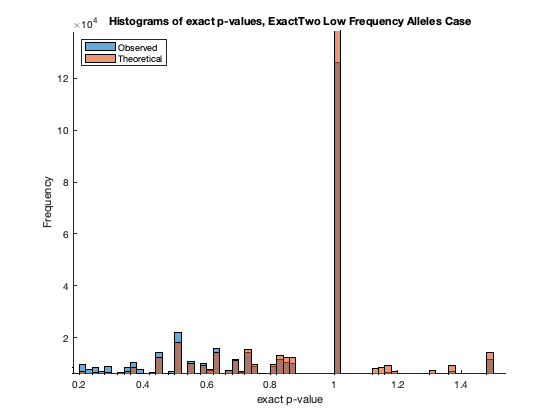

figure
hold on

histogram(round(McNemarsResult_Filtered_b_plus_c.ExactTwoLF_p_exact,6))
histogram(filtered_Exact_p_values_array_for_all_SNP)
legend('Observed','Theoretical', 'Location','northwest')
title('Histograms of exact p-values, ExactTwo Low Frequency Alleles Case')
xlabel('exact p-value')
ylabel('Frequency')
hold off

sort_predicted_mid_p_values_array_for_all_SNP = sort(Theoretical_Mid_p_values_array_for_all_SNP');
sort_observed_mid_p_values_array_for_all_SNP = sort(McNemarsResult_Filtered.ExactTwoLF_p_mid);
%Sorted_Predicted_vs_Observed = table(sort_predicted_minuslog10_mid_p_values_array_for_all_SNP,sort_observed_minuslog10_mid_p_values_for_all_SNP)


% filename = 'ExactlyTwoAllele_LowFrequency.xlsx';
writematrix(sort_predicted_mid_p_values_array_for_all_SNP, 'sort_predicted_mid_p_values_array_for_all_SNP.csv','Delimiter',',')
writematrix(sort_observed_mid_p_values_array_for_all_SNP, 'sort_observed_mid_p_values_array_for_all_SNP.csv','Delimiter',',')

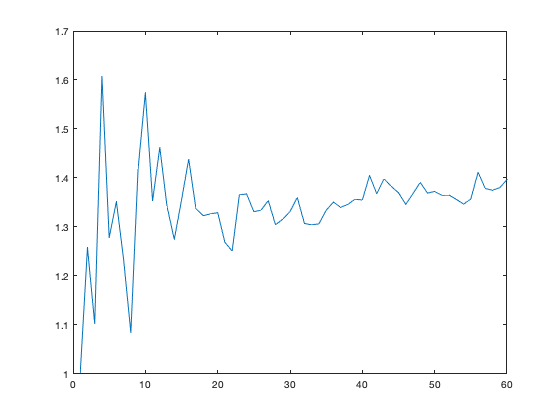

for n = 1:NumInformativePairs

    %compute normalization factor, total_mid_p for each b+c (Informative
    %Pair)

    rows_b_plus_c = McNemarsResult.("ExactOneHF_b+c") == n;
    total_mid_p(n) = sum(McNemarsResult.("ExactOneHF_p_mid")(rows_b_plus_c));

    for i=0:1:n
        b = i;
        c = n - i;
        rows_b_c = (McNemarsResult.("ExactOneHF_b+c") == (b + c) &  ...
            (McNemarsResult.("ExactOneHF_b") == b & ...
            (McNemarsResult.("ExactOneHF_c") == c)));
        Observed_Mid_p_Distro(b+c,i+1) = sum(McNemarsResult.("ExactOneHF_p_mid")(rows_b_c));

        Normalized_Observed_Mid_p_Distro(b+c,i+1) = sum(McNemarsResult.("ExactOneHF_p_mid")(rows_b_c))/total_mid_p(n);


    end
end


for n = 1:NumInformativePairs
    
    VarCheck(n) = var(Normalized_Observed_Mid_p_Distro(n,:))/var(Normalized_Theoretical_Mid_p_Distro(n,:));
    StdVCheck(n) = std(Normalized_Observed_Mid_p_Distro(n,:))/std(Normalized_Theoretical_Mid_p_Distro(n,:));
end

plot(VarCheck)

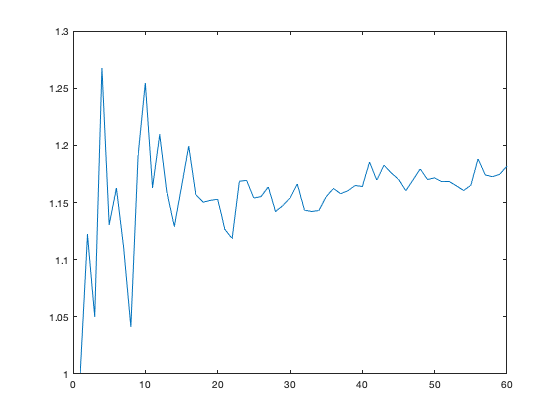

plot(StdVCheck)


for n = 1:NumInformativePairs

    %compute normalization factor, total_mid_p for each b+c (Informative
    %Pair)

    rows_b_plus_c = McNemarsResult.("ExactTwoLF_b+c") == n;
    total_mid_p(n) = sum(McNemarsResult.("ExactTwoLF_p_mid")(rows_b_plus_c));

    for i=0:1:n
        b = i;
        c = n - i;
        
        rows_b_c = (McNemarsResult.("ExactTwoLF_b+c") == (b + c) &  ...
            (McNemarsResult.("ExactTwoLF_b") == b & ...
            (McNemarsResult.("ExactTwoLF_c") == c)));

    Theo_Scale_Mid_p(n) =  max(Theoretical_Mid_p_Distro(n,:)/max(Observed_Mid_p_Distro(n,:)));
    Theo_Normalized_Observed_Mid_p_Distro(b+c,i+1) = sum(McNemarsResult.("ExactTwoLF_p_mid")(rows_b_c)) * Theo_Scale_Mid_p(n) ;
    end
end


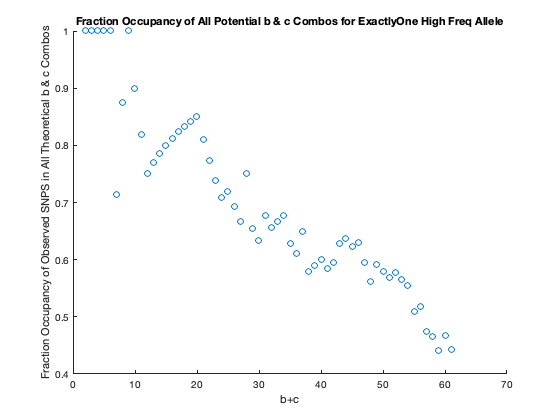

% Compute percent occupancy of the theoretical combinations of b and c for a given b+c

for n = 1:NumInformativePairs
    
    NumberOfTheoretical_b_and_c_Combos(n) = n + 1;
    NumberofObserved_b_and_c_Combos(n) = nnz(Observed_Mid_p_Distro(n,:));
    
end

FractionOccupancy = NumberofObserved_b_and_c_Combos./NumberOfTheoretical_b_and_c_Combos;
scatter(NumberOfTheoretical_b_and_c_Combos,FractionOccupancy)
ylabel('Fraction Occupancy of Observed SNPS in All Theoretical b & c Combos')
xlabel('b+c')
title('Fraction Occupancy of All Potential b & c Combos for Exactly Two Low Freq Allele')

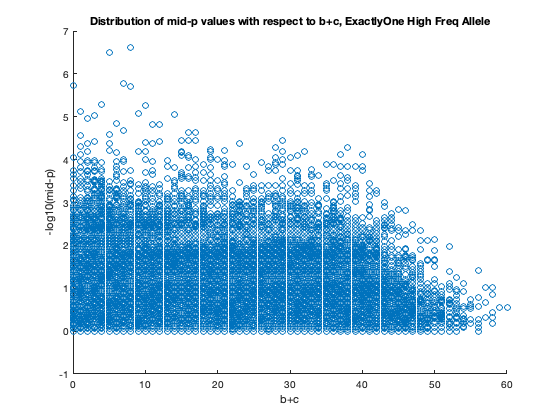



% How do these levels compare with Observed SNP with the lowest mid-p (highest -log10(mid-p)
scatter(McNemarsResult.("ExactTwoLF_b+c"),McNemarsResult.("-log10(ExactOneHF_mid_p)"))
ylabel('-log10(mid-p)')
xlabel('b+c')
title('Distribution of mid-p values with respect to b+c, ExactlyOne High Freq Allele')

% the lowest mid-p (highest -log10(mid-p) occurs with b+c = 52 followed by
% b+c = 45.  After b+c = 52, as the b+c the  mid-p values go up 

% array of b+c values, increasing by 1 , from 1 to number of pairs
% this array identifies b+c values to perform statistical analysis as
% there is sufficient occupancy
% idx_55 can have runs of 1's and 0's interspersed, depending on the
% distribution. Setup for loop and check that value of idx_55 == 1 before
% adding array of mid-p values correspinds
FO_idx = FractionOccupancy > 0.5;
FracOccupancyLength = length(FO_idx);

% find first nonzero occurance of in FO_ndx, need to start there in for
% loop below

ForStart = find(FO_idx,1);

for i = ForStart:1:FracOccupancyLength

    if FO_idx(i) == 1 && i == ForStart

        SufficientNormalizedObservedOccupancyArray =  nonzeros(Normalized_Observed_Mid_p_Distro(i,:));
        temp_index = find(Normalized_Observed_Mid_p_Distro(i,:));
        SufficientNormalizedExpectedOccupancyArray = Normalized_Theoretical_Mid_p_Distro(i,temp_index);

    elseif FO_idx(i) == 1 && i > ForStart 

        SufficientNormalizedObservedOccupancyArray = vertcat(SufficientNormalizedObservedOccupancyArray,nonzeros(Normalized_Observed_Mid_p_Distro(i,:)));
        temp_index = find(Normalized_Observed_Mid_p_Distro(i,:));
        SufficientNormalizedExpectedOccupancyArray =  horzcat(SufficientNormalizedExpectedOccupancyArray,Theoretical_Mid_p_Distro(i,temp_index) );
    end
end

Sorted_SufficientNormalizedObservedOcccupancyArray = sort(SufficientNormalizedObservedOccupancyArray);
min_Sorted_SufficientNormalizedObservedOcccupancyArray = min(Sorted_SufficientNormalizedObservedOcccupancyArray);
max_Sorted_SufficientNormalizedObservedOcccupancyArray = max(Sorted_SufficientNormalizedObservedOcccupancyArray);
Sorted_SufficientNormalizedExpectedOccupancyArray = sort(SufficientNormalizedExpectedOccupancyArray');
min_Sorted_SufficientExpectedOccupancyArray = min(Sorted_SufficientNormalizedExpectedOccupancyArray);
max_Sorted_SufficientExpectedOccupancyArray = max(Sorted_SufficientNormalizedExpectedOccupancyArray);


scatter(-log10(SufficientNormalizedExpectedOccupancyArray), -log10(SufficientNormalizedObservedOccupancyArray))

qqplot(-log10(SufficientNormalizedExpectedOccupancyArray),-log10(SufficientNormalizedObservedOccupancyArray))

% array of b+c values, increasing by 1 , from 1 to number of pairs
% this array identifies b+c values to perform statistical analysis as
% there is sufficient occupancy
% idx_55 can have runs of 1's and 0's interspersed, depending on the
% distribution. Setup for loop and check that value of idx_55 == 1 before
% adding array of mid-p values correspinds
FO_idx = FractionOccupancy > 0.5;
FracOccupancyLength = length(FO_idx);

% find first nonzero occurance of in FO_ndx, need to start there in for
% loop below

ForStart = find(FO_idx,1);

for i = ForStart:1:FracOccupancyLength

    if FO_idx(i) == 1 && i == ForStart

        SufficientTheoNormalizedObservedOccupancyArray =  nonzeros(Theo_Normalized_Observed_Mid_p_Distro(i,:));
        temp_index = find(Theo_Normalized_Observed_Mid_p_Distro(i,:));
        SufficientNormalizedExpectedOccupancyArray = Normalized_Theoretical_Mid_p_Distro(i,temp_index);

    elseif FO_idx(i) == 1 && i > ForStart 

        SufficientTheoNormalizedObservedOccupancyArray = vertcat(SufficientTheoNormalizedObservedOccupancyArray,nonzeros(Theo_Normalized_Observed_Mid_p_Distro(i,:)));
        temp_index = find(Theo_Normalized_Observed_Mid_p_Distro(i,:));
        SufficientNormalizedExpectedOccupancyArray =  horzcat(SufficientNormalizedExpectedOccupancyArray,Theoretical_Mid_p_Distro(i,temp_index) );
    end
end



qqplot(-log10(SufficientNormalizedExpectedOccupancyArray),-log10(SufficientTheoNormalizedObservedOccupancyArray))

% Find elements in theoretical distro matching those in observed. Not all
% theoretical elements will be present in observed arrays of mid-p values

% find non-zero elments in observed

% idx = Normalized_Observed_Mid_p_Distro > 0;
idx = find(Normalized_Observed_Mid_p_Distro);

Sorted_Normalized_Observed_Mid_p_Vector = sort(Normalized_Observed_Mid_p_Distro(idx));
Sorted_Observed_Mid_p_Vector = sort(Observed_Mid_p_Distro(idx));

% is it necessary to renormalize the remaining theoretical elements ?

%[nonzero_observed_row,nonzero_observed_col] = find(Normalized_Observed_Mid_p_Distro);

Sorted_Theoretical_Normalized_mid_p_Vector = sort(Normalized_Theoretical_Mid_p_Distro(idx));

Sorted_Theoretical_Mid_p_Vector = sort(Theoretical_Mid_p_Distro(idx));

qqplot(-log10(Sorted_Theoretical_Normalized_mid_p_Vector),-log10(Sorted_Normalized_Observed_Mid_p_Vector))
ylabel('Quantitles for -log10 normalized Observed mid-p (sorted)')
xlabel('Quantitles for -log10 normalized Theoretical mid-p (sorted)')
title('QQ Plot for ExactlyOne High Frequency Allele')

xlim('auto')
ylim('auto')


qqplot(-log10(Sorted_Theoretical_Normalized_mid_p_Vector),-log10(Sorted_Observed_Mid_p_Vector))
ylabel('Quantitles for -log10 Observed mid-p (sorted)')
xlabel('Quantitles for -log10 normalized Theoretical mid-p (sorted)')
title('QQ Plot for ExactlyOne High Frequency Allele')

case 2 ExactlyTwoAllele High Frequency 